ThreeLevelSurface Analysis Script to replicate the Image Preprocessing

================================================================

SECTION 1: SETUP AND PARAMETERS

================================================================

pixelSizeXY = 103;
pixelSizeZ = 205.8;
timeInterval = 1;

scales = [1, 1.5, 2,];
nSTDsurface = 2;
insideGamma = 0.7;
insideBlur = 2;
insideDilateRadius = 5;
insideErodeRadius = 6.5;

imageDirectory = '/Users/philippkaintoch/Documents/Projects/01_Bleb3D/Datensatz/3D_Lightsheet/1_shortMovie_BAIAP2_OE/ch1t0';
saveDirectory = '/Users/philippkaintoch/Documents/Projects/01_Bleb3D/Output/Batch8';

================================================================

SECTION 2: DATA LOADING

================================================================

if ~isfolder(saveDirectory), mkdir(saveDirectory); end
MD = makeMovieDataOneChannel(imageDirectory, saveDirectory, pixelSizeXY, pixelSizeZ, timeInterval);

Checking channels
Saving movie
Sanity check is finished!


Load the Data 

image3D_original = im2double(MD.getChannel(1).loadStack(1));
fprintf('Original image size: %d x %d x %d\n', size(image3D_original));

Original image size: 768 x 270 x 200


fprintf('Original value range: %.4f to %.4f\n', min(image3D_original(:)), max(image3D_original(:)));

Original value range: 0.0000 to 0.0416


Display original image (middle slice)

%figure; imagesc(image3D_original(:,:,round(end/2))); 
%colormap(gray); axis equal; axis off; title('Original Image');
%colorbar;

%figure;
% volshow(image3D_original);

================================================================

SECTION 3: MAKE VOXELS ISOTROPIC

================================================================

Purpose: Adjust image so that voxels are cubic (same size in all dimensions)

--> Ensures morphological operations work correctly regardless of acquisition settings

image3D = make3DImageVoxelsSymmetric(image3D_original, MD.pixelSize_, MD.pixelSizeZ_);

fprintf('Isotropic image size: %d x %d x %d\n', size(image3D));

Isotropic image size: 768 x 270 x 399


fprintf('Scaling factor Z: %.2f\n', pixelSizeZ/pixelSizeXY);

Scaling factor Z: 2.00



%figure;
%subplot(1,2,1); imagesc(image3D_original(:,:,round(end/2))); 
%colormap(gray); axis equal; title('Original'); colorbar;
%subplot(1,2,2); imagesc(image3D(:,:,round(end/2))); 
%colormap(gray); axis equal; title('Isotropic'); colorbar;

================================================================

SECTION 4: ADD BLACK BORDER

================================================================

Purpose: Prevent edge artifacts during filtering and morphological operations

--> Method: Adds 1-pixel border filled with median intensity value

Calculates median intensity of entire 3D volume. Creates new volume that's 2 pixels larger in each dimension. Fills border with median value. Copies original data into center. In general creates like a **smooth transition** 

% Original image (e.g., 5x5 for simplicity):
% [Actual cell/image data]
% 0.8  0.7  0.6  0.5  0.4
% 0.7  0.9  0.8  0.6  0.3
% 0.6  0.8  0.9  0.7  0.5
% 0.5  0.7  0.8  0.8  0.6
% 0.4  0.6  0.7  0.7  0.5

% Median value = 0.6 (example)

% After border (now 7x7):
% 0.6  0.6  0.6  0.6  0.6  0.6  0.6  ← Border row
% 0.6  0.8  0.7  0.6  0.5  0.4  0.6  ← Border + Original data
% 0.6  0.7  0.9  0.8  0.6  0.3  0.6
% 0.6  0.6  0.8  0.9  0.7  0.5  0.6
% 0.6  0.5  0.7  0.8  0.8  0.6  0.6
% 0.6  0.4  0.6  0.7  0.7  0.5  0.6
% 0.6  0.6  0.6  0.6  0.6  0.6  0.6  ← Border row
%  ↑                               ↑
% Border                        Border
% column                        column

image3D_bordered = addBlackBorder(image3D, 1);

fprintf('Size after border: %d x %d x %d\n', size(image3D_bordered));

Size after border: 770 x 272 x 401


fprintf('Border value: %.4f (median of original)\n', median(image3D(:)));

Border value: 0.0001 (median of original)



fprintf('Original size: %d x %d x %d\n', size(image3D));

Original size: 768 x 270 x 399


fprintf('Bordered size: %d x %d x %d\n', size(image3D_bordered));

Bordered size: 770 x 272 x 401


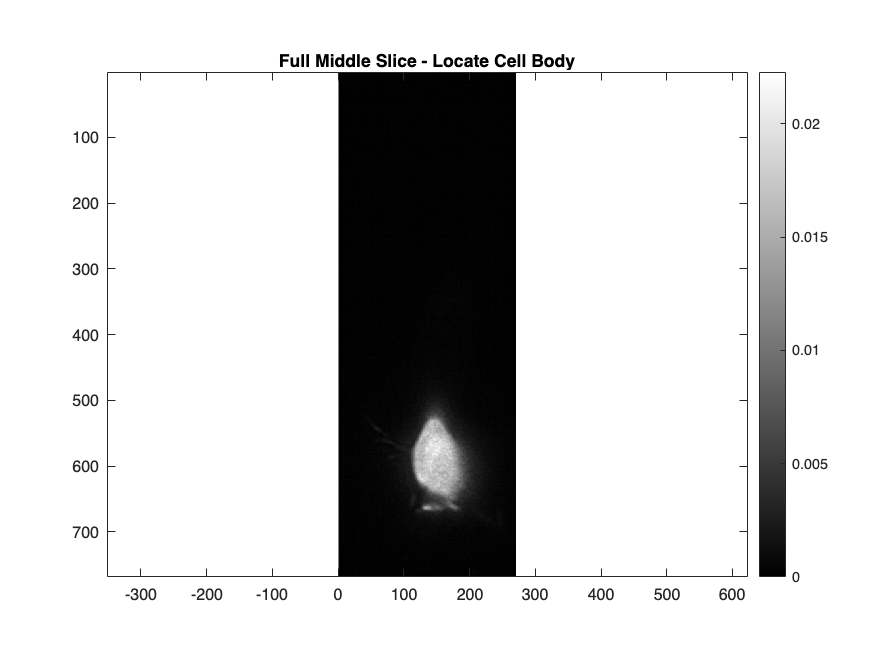


figure;
imagesc(image3D(:,:,round(end/2)));
colormap(gray); axis equal; 
title('Full Middle Slice - Locate Cell Body');
colorbar;

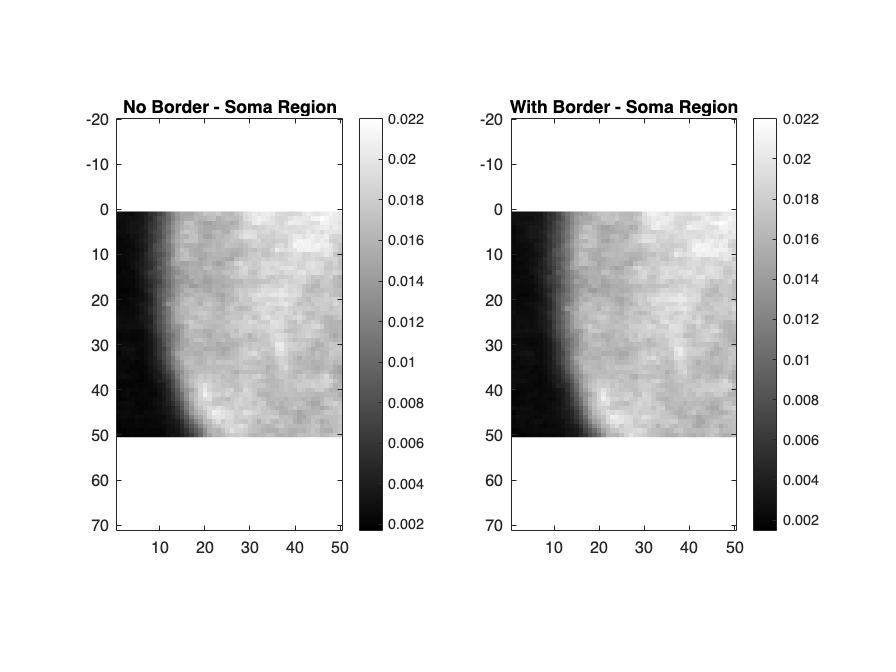


soma_y = 600;
soma_x = 130; 

% Extract 50x50 region centered on soma
y_range = (soma_y-25):(soma_y+24);
x_range = (soma_x-25):(soma_x+24);

figure;
subplot(1,2,1); 
imagesc(image3D(y_range, x_range, round(end/2)));
colormap(gray); axis equal; title('No Border - Soma Region'); colorbar;

subplot(1,2,2); 
imagesc(image3D_bordered(y_range, x_range, round(end/2)));
colormap(gray); axis equal; title('With Border - Soma Region'); colorbar;

================================================================

SECTION 5: LEVEL 1 - INSIDE PROCESSING (GAMMA CORRECTION)

================================================================

Purpose: Enhance dim interior regions of the cell

Method: Raise intensity to power < 1 (brightens dark regions more than bright regions)

Gamma < 1: Enhances shadows, Gamma > 1: Enhances highlights

image3D_gamma = image3D_bordered.^insideGamma;

fprintf('Gamma correction applied: %.2f\n', insideGamma);

Gamma correction applied: 0.70


fprintf('Value range after gamma: %.4f to %.4f\n', min(image3D_gamma(:)), max(image3D_gamma(:)));

Value range after gamma: 0.0000 to 0.1080


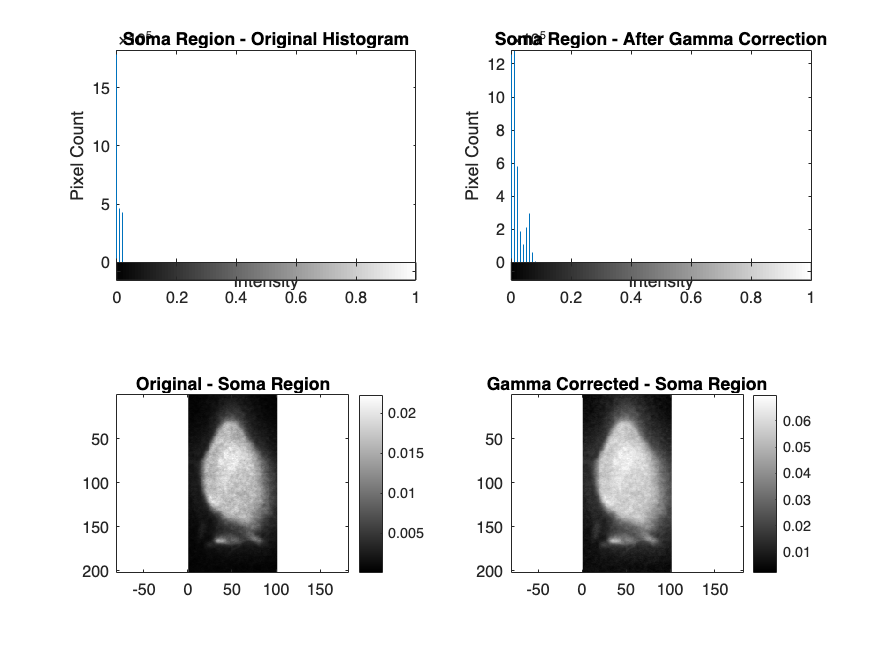


soma_y_range = 500:700;  % Y coordinates
soma_x_range = 100:200;  % X coordinates

soma_region_bordered = image3D_bordered(soma_y_range, soma_x_range, :);
soma_region_gamma = image3D_gamma(soma_y_range, soma_x_range, :);

figure;
subplot(2,2,1); 
imhist(soma_region_bordered(:), 100); 
title('Soma Region - Original Histogram');
ylabel('Pixel Count'); xlabel('Intensity');

subplot(2,2,2); 
imhist(soma_region_gamma(:), 100); 
title('Soma Region - After Gamma Correction');
ylabel('Pixel Count'); xlabel('Intensity');

subplot(2,2,3); 
imagesc(image3D_bordered(soma_y_range, soma_x_range, round(end/2)));
colormap(gray); axis equal; 
title('Original - Soma Region'); colorbar;

subplot(2,2,4); 
imagesc(image3D_gamma(soma_y_range, soma_x_range, round(end/2)));
colormap(gray); axis equal; 
title('Gamma Corrected - Soma Region'); colorbar;

================================================================

SECTION 6: LEVEL 1 - INSIDE PROCESSING (GAUSSIAN BLUR)

================================================================

Purpose: Reduce noise and create smoother regions for better thresholding

Method: Convolve with 3D Gaussian kernel (sigma = 2 pixels)

image3D_blurred = filterGauss3D(image3D_gamma, insideBlur);

fprintf('Gaussian blur applied with sigma = %.1f\n', insideBlur);

Gaussian blur applied with sigma = 2.0


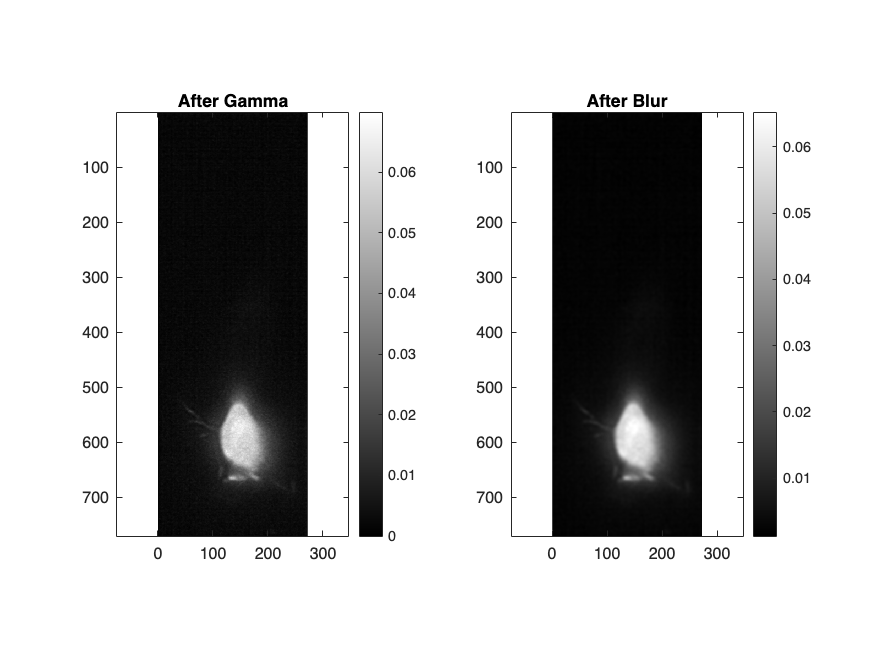


% Show blurring effect
figure;
subplot(1,2,1); imagesc(image3D_gamma(:,:,round(end/2))); 
colormap(gray); axis equal; title('After Gamma'); colorbar;
subplot(1,2,2); imagesc(image3D_blurred(:,:,round(end/2))); 
colormap(gray); axis equal; title('After Blur'); colorbar;

================================================================

SECTION 7: LEVEL 1 - INSIDE PROCESSING (OTSU THRESHOLD)

================================================================

Purpose: Automatically determine optimal threshold to separate foreground from background

Method: Otsu's method minimizes intra-class variance

insideThreshValue = thresholdOtsu(image3D_blurred(:));
image3D_thresh_binary = image3D_blurred > insideThreshValue;

fprintf('Otsu threshold value: %.4f\n', insideThreshValue);

Otsu threshold value: 0.0249


fprintf('Pixels above threshold: %.1f%%\n', 100*sum(image3D_thresh_binary(:))/numel(image3D_thresh_binary));

Pixels above threshold: 1.2%


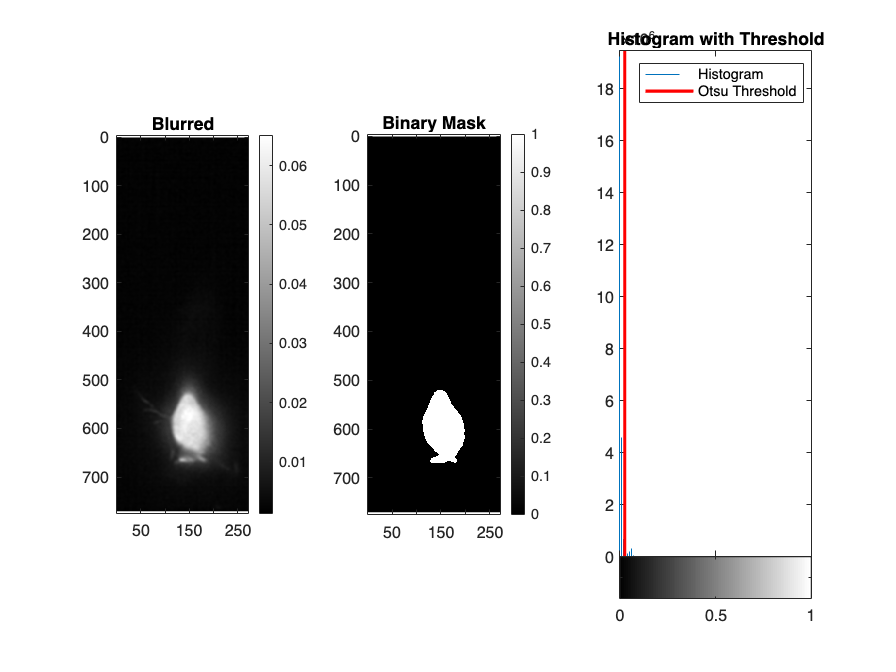


% Show thresholding result
figure;
subplot(1,3,1); imagesc(image3D_blurred(:,:,round(end/2))); 
colormap(gray); axis equal; title('Blurred'); colorbar;
subplot(1,3,2); imagesc(image3D_thresh_binary(:,:,round(end/2))); 
colormap(gray); axis equal; title('Binary Mask'); colorbar;
subplot(1,3,3); imhist(image3D_blurred(:), 100); hold on;
line([insideThreshValue insideThreshValue], ylim, 'Color', 'r', 'LineWidth', 2);
title('Histogram with Threshold'); legend('Histogram', 'Otsu Threshold');

================================================================

SECTION 8: LEVEL 1 - INSIDE PROCESSING (MORPHOLOGICAL DILATION)

================================================================

Purpose: Expand detected regions to fill small gaps and connect nearby objects

Method: Convolve with spherical structuring element

% Conceptual process:
% 1. Takes a structuring element (a "brush" shape)
% 2. Places it at every white pixel in the image
% 3. Turns all pixels covered by the brush to white

% Visual example in 2D (easier to understand):
% Original:        Structuring       After Dilation:
%                  Element (3x3):    
% 0 0 0 0 0        1 1 1            0 1 1 1 0
% 0 1 1 0 0   +    1 1 1      =     1 1 1 1 1
% 0 0 1 0 0        1 1 1            1 1 1 1 1
% 0 0 0 0 0                         0 1 1 1 0

Dilation is a fundamental morphological operation that **expands** or **grows** objects in a binary image. Think of it like "fattening" all the white regions.

sphereDilate = makeSphere3D(insideDilateRadius);
image3D_dilated = imdilate(image3D_thresh_binary, sphereDilate);

fprintf('Dilation applied with radius = %.1f pixels\n', insideDilateRadius);

Dilation applied with radius = 5.0 pixels


fprintf('Pixels after dilation: %.1f%% (was %.1f%%)\n', ...
    100*sum(image3D_dilated(:))/numel(image3D_dilated), ...
    100*sum(image3D_thresh_binary(:))/numel(image3D_thresh_binary));

Pixels after dilation: 1.6% (was 1.2%)


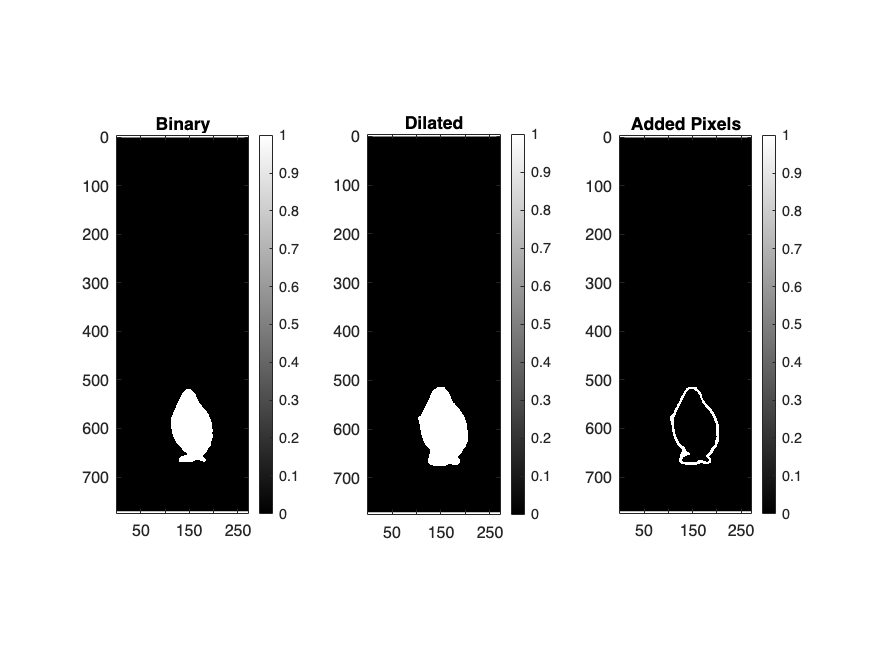


% Show dilation effect
figure;
subplot(1,3,1); imagesc(image3D_thresh_binary(:,:,round(end/2))); 
colormap(gray); axis equal; title('Binary'); colorbar;
subplot(1,3,2); imagesc(image3D_dilated(:,:,round(end/2))); 
colormap(gray); axis equal; title('Dilated'); colorbar;
subplot(1,3,3); imagesc(image3D_dilated(:,:,round(end/2)) - image3D_thresh_binary(:,:,round(end/2))); 
colormap(gray); axis equal; title('Added Pixels'); colorbar;

================================================================

SECTION 9: LEVEL 1 - INSIDE PROCESSING (HOLE FILLING)

================================================================

Purpose: Fill interior holes within detected regions

Method: Fill holes slice-by-slice using morphological reconstruction

image3D_filled = image3D_dilated;
for h = 1:size(image3D_filled, 3)
    image3D_filled(:,:,h) = imfill(image3D_filled(:,:,h), 'holes');
end

fprintf('Hole filling completed on %d slices\n', size(image3D_filled, 3));

Hole filling completed on 401 slices


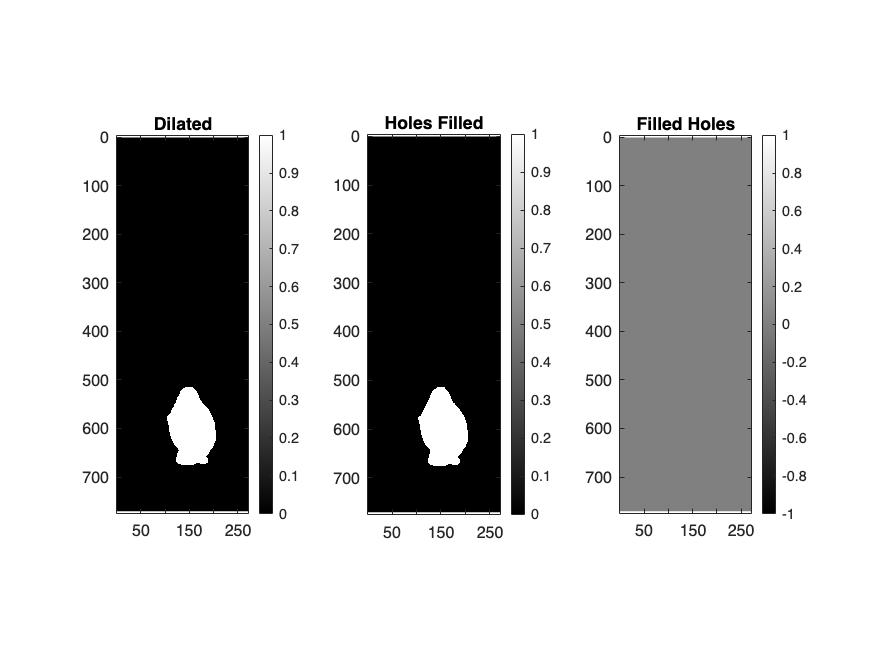


% Show hole filling effect
figure;
subplot(1,3,1); imagesc(image3D_dilated(:,:,round(end/2))); 
colormap(gray); axis equal; title('Dilated'); colorbar;
subplot(1,3,2); imagesc(image3D_filled(:,:,round(end/2))); 
colormap(gray); axis equal; title('Holes Filled'); colorbar;
subplot(1,3,3); imagesc(image3D_filled(:,:,round(end/2)) - image3D_dilated(:,:,round(end/2))); 
colormap(gray); axis equal; title('Filled Holes'); colorbar;

================================================================

SECTION 10: LEVEL 1 - INSIDE PROCESSING (MORPHOLOGICAL EROSION)

================================================================

Purpose: Contract regions back to original size and smooth boundaries

Method: Convolve with spherical structuring element (erosion)

sphereErode = makeSphere3D(insideErodeRadius);
image3D_eroded = double(imerode(image3D_filled, sphereErode));

fprintf('Erosion applied with radius = %.1f pixels\n', insideErodeRadius);

Erosion applied with radius = 6.5 pixels


fprintf('Pixels after erosion: %.1f%% (was %.1f%%)\n', ...
    100*sum(image3D_eroded(:))/numel(image3D_eroded), ...
    100*sum(image3D_filled(:))/numel(image3D_filled));

Pixels after erosion: 1.0% (was 1.6%)


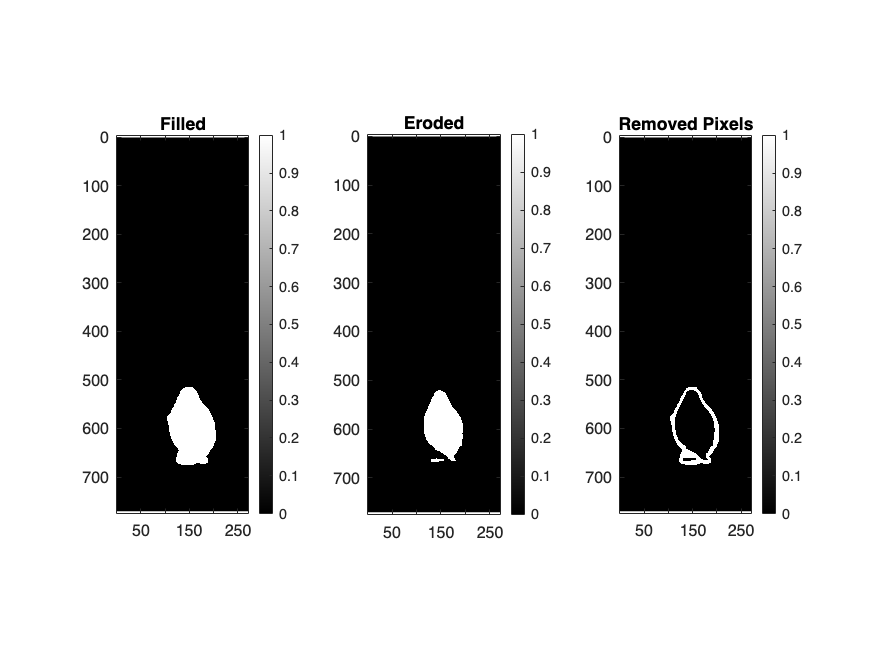


% Show erosion effect
figure;
subplot(1,3,1); imagesc(image3D_filled(:,:,round(end/2))); 
colormap(gray); axis equal; title('Filled'); colorbar;
subplot(1,3,2); imagesc(image3D_eroded(:,:,round(end/2))); 
colormap(gray); axis equal; title('Eroded'); colorbar;
subplot(1,3,3); imagesc(image3D_filled(:,:,round(end/2)) - image3D_eroded(:,:,round(end/2))); 
colormap(gray); axis equal; title('Removed Pixels'); colorbar;

================================================================

SECTION 11: LEVEL 1 - INSIDE PROCESSING (FINAL SMOOTHING)

================================================================

Purpose: Create smooth transitions for better mesh generation

Method: Light Gaussian smoothing (sigma = 1)

image3D_inside_final = filterGauss3D(image3D_eroded, 1);

fprintf('Final smoothing applied (sigma = 1)\n');

Final smoothing applied (sigma = 1)


fprintf('Inside level processing complete\n');

Inside level processing complete


fprintf('Final range: %.4f to %.4f\n', min(image3D_inside_final(:)), max(image3D_inside_final(:)));

Final range: 0.0000 to 1.0000


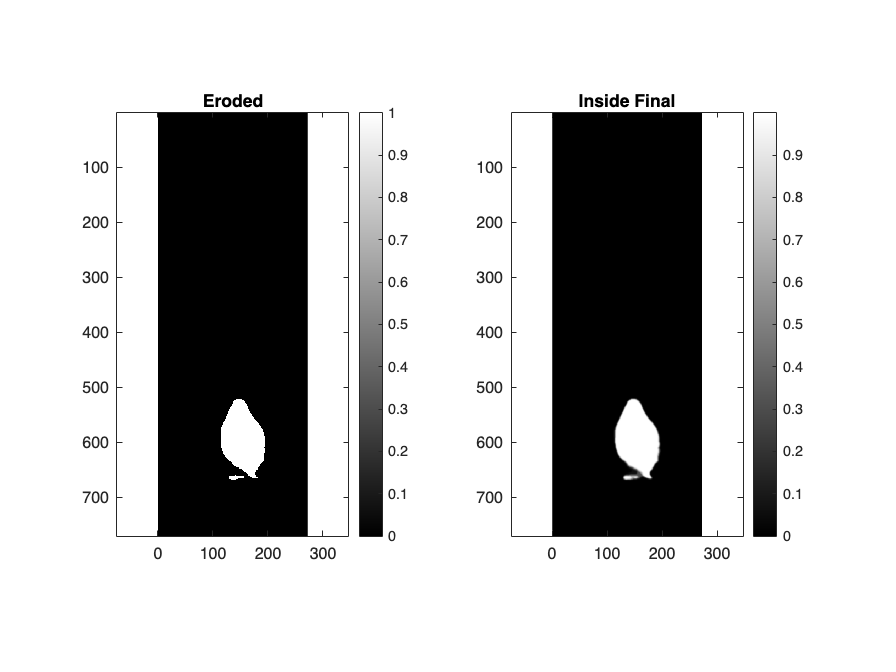


% Show final inside result
figure;
subplot(1,2,1); imagesc(image3D_eroded(:,:,round(end/2))); 
colormap(gray); axis equal; title('Eroded'); colorbar;
subplot(1,2,2); imagesc(image3D_inside_final(:,:,round(end/2))); 
colormap(gray); axis equal; title('Inside Final'); colorbar;

================================================================

SECTION 12: LEVEL 2 - CELL PROCESSING (NORMALIZATION)

================================================================

Purpose: Create normalized intensity image for overall cell contrast

Method: Subtract Otsu threshold, then normalize by standard deviation

% Calculate Otsu threshold for normalization
cellThreshValue = thresholdOtsu(image3D_bordered(:));
fprintf('Cell Otsu threshold: %.4f\n', cellThreshValue);

Cell Otsu threshold: 0.0080



% Subtract threshold and normalize
image3D_cell_subtracted = image3D_bordered - cellThreshValue;
image3D_cell_normalized = image3D_cell_subtracted / std(image3D_cell_subtracted(:));

fprintf('Cell image normalized\n');

Cell image normalized


fprintf('Range after normalization: %.3f to %.3f\n', min(image3D_cell_normalized(:)), max(image3D_cell_normalized(:)));

Range after normalization: -4.992 to 20.966


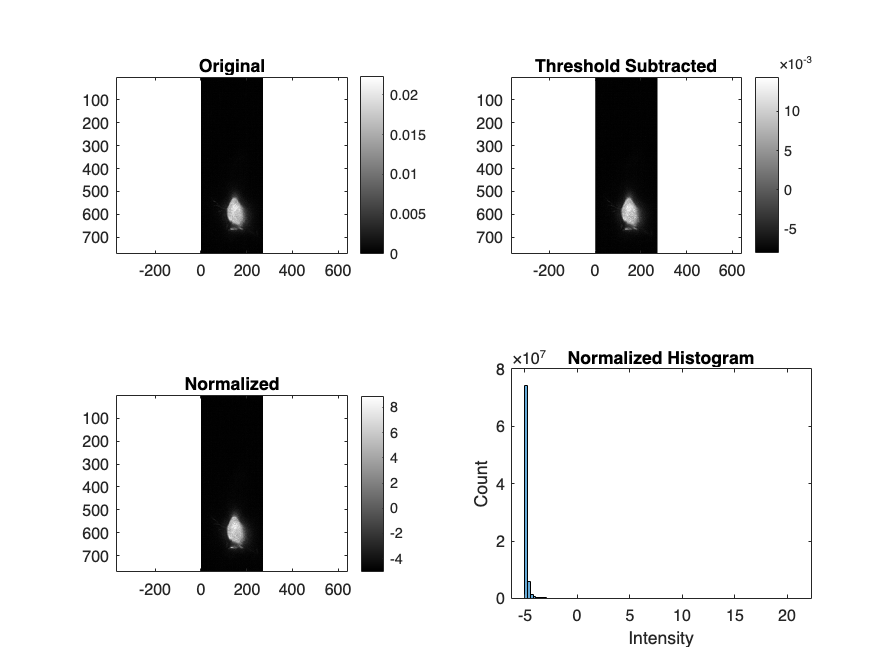


% Show normalization effect
figure;
subplot(2,2,1); imagesc(image3D_bordered(:,:,round(end/2))); 
colormap(gray); axis equal; title('Original'); colorbar;
subplot(2,2,2); imagesc(image3D_cell_subtracted(:,:,round(end/2))); 
colormap(gray); axis equal; title('Threshold Subtracted'); colorbar;
subplot(2,2,3); imagesc(image3D_cell_normalized(:,:,round(end/2))); 
colormap(gray); axis equal; title('Normalized'); colorbar;
subplot(2,2,4); histogram(image3D_cell_normalized(:), 100);
    title('Normalized Histogram'); xlabel('Intensity'); ylabel('Count');

================================================================

SECTION 13: LEVEL 3 - SURFACE PROCESSING (MULTISCALE FILTER)

================================================================

Purpose: Detect membrane/surface structures at multiple scales

Method: Apply second-derivative-based filters at different scales, keep maximum response

fprintf('Applying multiscale surface filter...\n');

Applying multiscale surface filter...


fprintf('Scales: [%.1f, %.1f, %.1f]\n', scales);

Scales: [1.0, 1.5, 2.0]



q.SigmasXY = scales; 
q.SigmasZ = scales; 
q.WeightZ = 1;
[maxResp, ~, ~, ~, maxRespScale] = multiscaleSurfaceFilter3D(image3D_cell_normalized, q);

fprintf('Surface filter response computed\n');

Surface filter response computed


fprintf('Response range: %.4f to %.4f\n', min(maxResp(:)), max(maxResp(:)));

Response range: 0.0000 to 2.6687


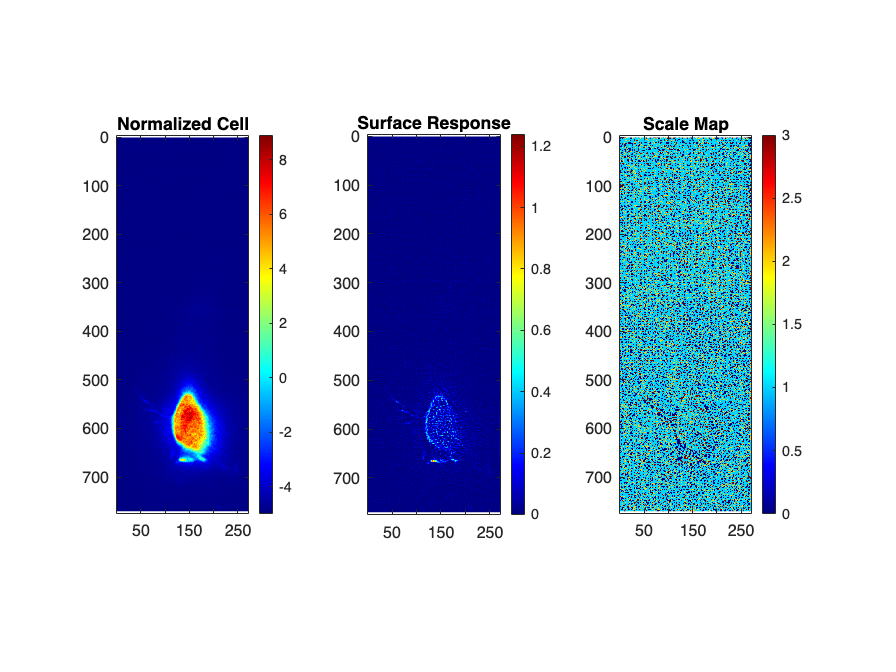


% Show surface filter response
figure;
subplot(1,3,1); imagesc(image3D_cell_normalized(:,:,round(end/2))); 
colormap(gray); axis equal; title('Normalized Cell'); colorbar;
subplot(1,3,2); imagesc(maxResp(:,:,round(end/2))); 
colormap(gray); axis equal; title('Surface Response'); colorbar;
subplot(1,3,3); imagesc(maxRespScale(:,:,round(end/2))); 
colormap(jet); axis equal; title('Scale Map'); colorbar;

================================================================

SECTION 14: LEVEL 3 - SURFACE PROCESSING (THRESHOLDING)

================================================================

Purpose: Threshold surface response and normalize for combination

Method: Use mean + N*std as threshold, then normalize by std

% Calculate surface threshold
surfBackMean = mean(maxResp(:));
surfBackSTD = std(maxResp(:));
surfThresh = surfBackMean + (nSTDsurface * surfBackSTD);

fprintf('Surface statistics:\n');

Surface statistics:


fprintf('  Mean: %.4f, Std: %.4f\n', surfBackMean, surfBackSTD);

  Mean: 0.0098, Std: 0.0297


fprintf('  Threshold: %.4f (mean + %.1f*std)\n', surfThresh, nSTDsurface);

  Threshold: 0.0691 (mean + 2.0*std)



% Apply threshold and normalize
image3D_surface_thresholded = maxResp - surfThresh;
image3D_surface_final = image3D_surface_thresholded / std(image3D_surface_thresholded(:));

fprintf('Surface processing complete\n');

Surface processing complete


fprintf('Final range: %.3f to %.3f\n', min(image3D_surface_final(:)), max(image3D_surface_final(:)));

Final range: -2.329 to 87.604


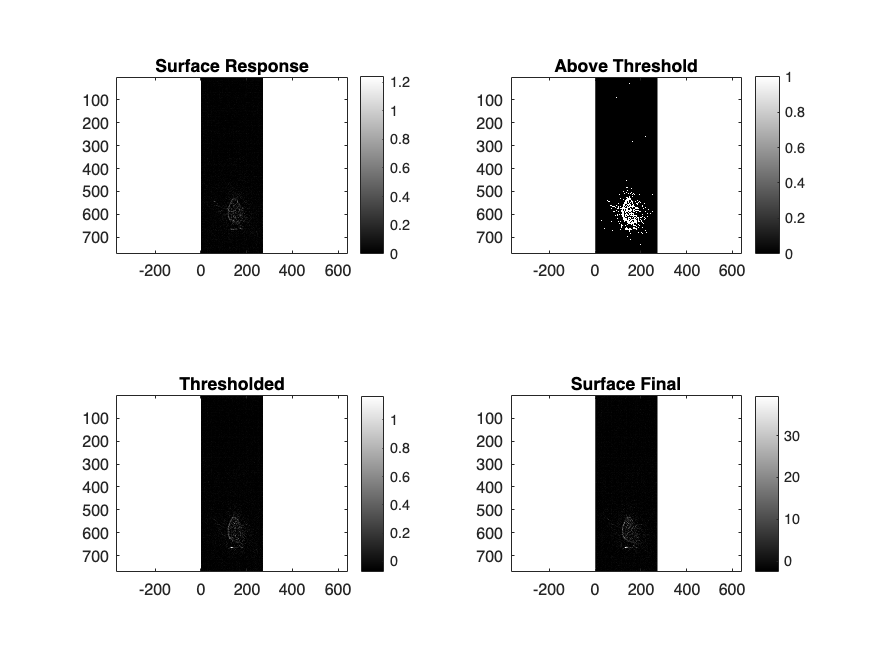


% Show surface processing
figure;
subplot(2,2,1); imagesc(maxResp(:,:,round(end/2))); 
colormap(gray); axis equal; title('Surface Response'); colorbar;
subplot(2,2,2); imagesc(maxResp(:,:,round(end/2)) > surfThresh); 
colormap(gray); axis equal; title('Above Threshold'); colorbar;
subplot(2,2,3); imagesc(image3D_surface_thresholded(:,:,round(end/2))); 
colormap(gray); axis equal; title('Thresholded'); colorbar;
subplot(2,2,4); imagesc(image3D_surface_final(:,:,round(end/2))); 
colormap(gray); axis equal; title('Surface Final'); colorbar;

================================================================

SECTION 15: COMBINE ALL THREE LEVELS

================================================================

Purpose: Merge information from all three processing streams

Method: Take maximum value at each pixel across all three levels

combinedImage = max(max(image3D_inside_final, image3D_cell_normalized), image3D_surface_final);

fprintf('Three levels combined using MAX operation\n');

Three levels combined using MAX operation


fprintf('Combined range: %.3f to %.3f\n', min(combinedImage(:)), max(combinedImage(:)));

Combined range: 0.000 to 87.604


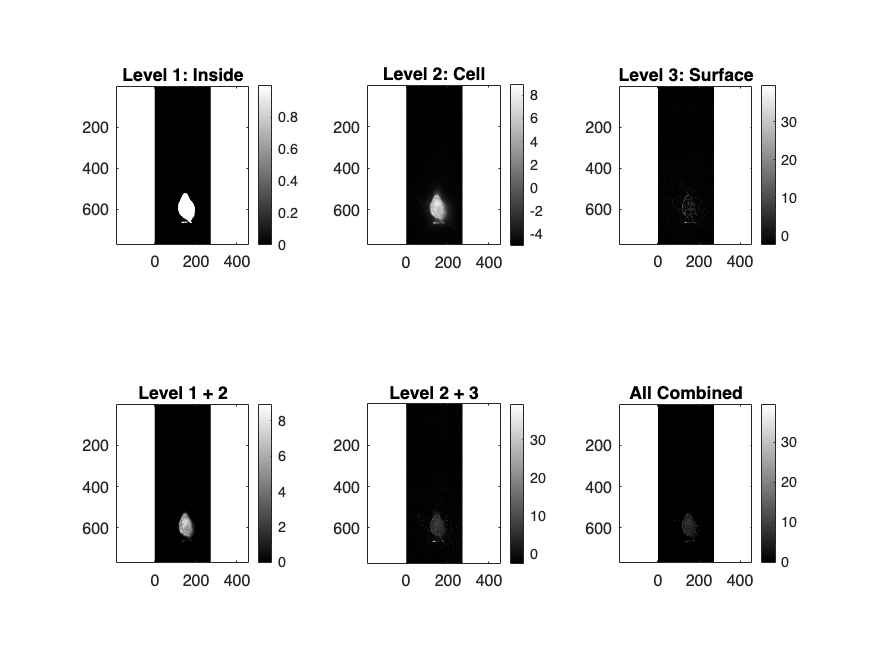


% Show combination process
figure;
subplot(2,3,1); imagesc(image3D_inside_final(:,:,round(end/2))); 
colormap(gray); axis equal; title('Level 1: Inside'); colorbar;
subplot(2,3,2); imagesc(image3D_cell_normalized(:,:,round(end/2))); 
colormap(gray); axis equal; title('Level 2: Cell'); colorbar;
subplot(2,3,3); imagesc(image3D_surface_final(:,:,round(end/2))); 
colormap(gray); axis equal; title('Level 3: Surface'); colorbar;

subplot(2,3,4); imagesc(max(image3D_inside_final(:,:,round(end/2)), image3D_cell_normalized(:,:,round(end/2)))); 
colormap(gray); axis equal; title('Level 1 + 2'); colorbar;
subplot(2,3,5); imagesc(max(image3D_cell_normalized(:,:,round(end/2)), image3D_surface_final(:,:,round(end/2)))); 
colormap(gray); axis equal; title('Level 2 + 3'); colorbar;
subplot(2,3,6); imagesc(combinedImage(:,:,round(end/2))); 
colormap(gray); axis equal; title('All Combined'); colorbar;

================================================================

SECTION 16: FINAL PROCESSING

================================================================

Purpose: Clean up combined image for mesh generation

Method: Fill holes, remove negatives, remove small components

% Fill holes
combinedImage_filled = imfill(combinedImage);
fprintf('Holes filled in combined image\n');

Holes filled in combined image



% Remove negative values
combinedImage_positive = combinedImage_filled;
combinedImage_positive(combinedImage_positive < 0) = 0;
negativePixels = sum(combinedImage_filled(:) < 0);
fprintf('Removed %d negative pixels\n', negativePixels);

Removed 0 negative pixels



% Remove disconnected components
level = 0.999;
combinedImage_final = removeDisconectedComponents(combinedImage_positive, level);
fprintf('Disconnected components removed (level = %.3f)\n', level);

Disconnected components removed (level = 0.999)


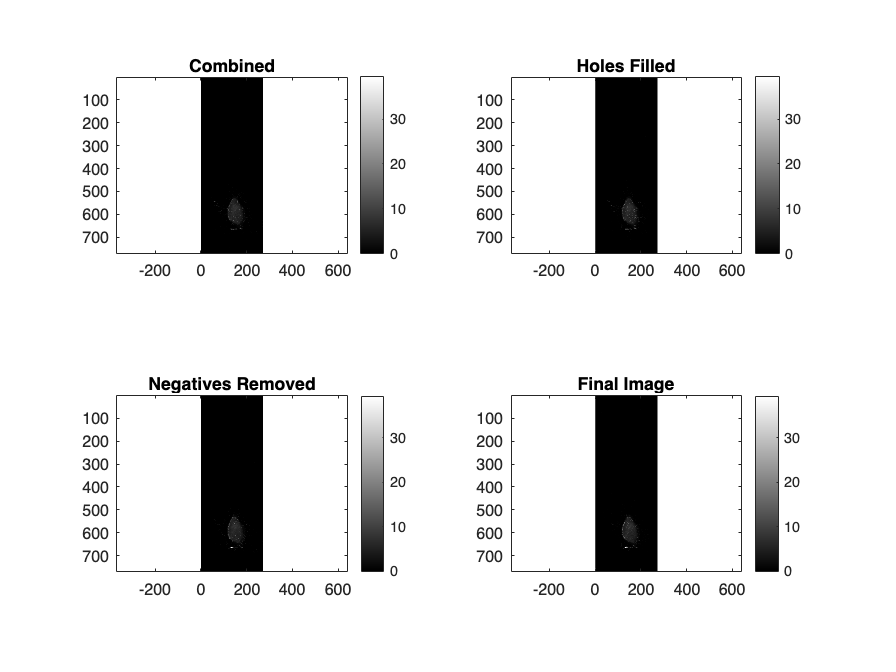


% Show final processing
figure;
subplot(2,2,1); imagesc(combinedImage(:,:,round(end/2))); 
colormap(gray); axis equal; title('Combined'); colorbar;
subplot(2,2,2); imagesc(combinedImage_filled(:,:,round(end/2))); 
colormap(gray); axis equal; title('Holes Filled'); colorbar;
subplot(2,2,3); imagesc(combinedImage_positive(:,:,round(end/2))); 
colormap(gray); axis equal; title('Negatives Removed'); colorbar;
subplot(2,2,4); imagesc(combinedImage_final(:,:,round(end/2))); 
colormap(gray); axis equal; title('Final Image'); colorbar;